 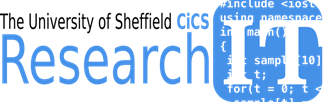

# **Exercises for Debugging and Improving Performance**

## Exercises 2 : Debugging a MATLAB Function or Script

In the examples directory under the ***numericalanalysis/interpol ***folder you will find a MATLAB script named interpol. 

- Make sure to make directory named ***numericalanalysis/interpol ***your “Current Directory” via the “***Current Folder***” window or alternatively add this folder to the MATLAB Path via *the context-menu* of the folder named root in the *current-folder window*

- Study this script and run it under the control of MATLAB debugger. Inspect the values of y1, y2 and y3 when the lagrange interpolation function is called. Are the x values evaluated in the correct range.

- Set break-point(s) within the while loop and start executing the script. When execution stops at each break-point hover the mouse over the variables in the debugger window to see their current values. Alternatively these values can also be viewed in the workspace window.  

## **Exercise 1: Using the Directory and Code Analyzer**

**Directory report - by selecting the current folder matlab_examples/casestudies.mission-mars/code-original**

**Select  CurrentFolder and from the down arrow in the top right corner select reports**

**run the code analyzer  - fix errors/ warnings and rerun**

**run the todo fix me report**

**FIXME**

**TODO**

## Exercises 2 : Debugging a MATLAB Function or Script

In the examples directory under the ***numericalanalysis/root_bisection***folder you will find a MATLAB script named **plotroot**. 

- Make sure to make directory named ***numericalanalysis/root_bisection ***your “Current Directory” via the “***Current Folder***” window or alternatively add this folder to the MATLAB Path via *the context-menu* of the folder named root in the *current-folder window*

- Study this script and run it under the control of MATLAB debugger.

- Set break-point(s) within the while loop and start executing the script. When execution stops at each break-point hover the mouse over the variables in the debugger window to see their current values. Alternatively these values can also be viewed in the workspace window.  

**Profiler**

**In the matlab vectorise folder**

**Run the genar.m under the profiler**

**Click run and time**

**Use **

**profile on**

**profile viewer**

**profile off**

**Note that bottleneck is mynewfun!**

**Spot the ; add them on re run profiler**

## exercise: bsxfun

Use `bsxfun` to add the row vector `c1` to each row of the matrix `c` and save the result in a 3-by-4 matrix named `result`.

c1 = [2.2 -1 3.1 4]
c = [11.1 2 1.5 -2.4; 2.2 -3.8 0.2 1.2; 4 4.1 -0.7 1.9]

%TODO call the bsxfun here
result = bsxfun(@plus,c1,c)

Use `bsxfun` to compare the row vector `c1` with each row of the matrix `c` using the comparison operation “greater than” and save the result in a 3-by-4 matrix named `result2`.

%TODO use bsxfun here 
result2 = bsxfun(@gt,c1,c)

## Nested Functions

**Info:** The function `findZero ` in the folder matlab_examples/usingmatlab/vectorize takes in the coefficients of a polynomial as inputs and finds the root of the polynomial nearest to the specified value.

The command `findZero``(``-2``,``1``,``3``,``2``)` returns an error because the function `polynomial` is a local function and does not have access to the variables `a`, `b`, and `c`. 

Modify the function file so that `polynomial` becomes a nested function and can access variables from the parent function's workspace.

function z = findZero(a,b,c,n)
% z = findZero(a,b,c) - Finds the root of the polynomial
% a*x^2 + b*x + c near n
z = fzero(@polynomial,n);

    function y = polynomial(x)
        y = a*x^2 + b*x + c;
    end
end